syms s w_0 zeta omega_n p_0 p_1 p_2 b_4 k_D k_p k_i a b
eqn1 =(s-w_0)*(s^2+2*zeta*omega_n*s+omega_n^2)

$$eqn1 = \left(s-w_{0}\right)\,\left({\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s+s^{2}\right)$$

eqn1 = expand(eqn1)

$$eqn1 = {\omega_{n}}^{2}\,s-w_{0}\,{\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s^{2}-2\,w_{0}\,\zeta \,\omega_{n}\,s+s^{3}-w_{0}\,s^{2}$$

eqn2 = (s-p_0)*(s-p_1)*(s-p_2)+b_4*(k_D*s^2+k_p*s+k_i)

$$eqn2 = b_{4}\,\left(k_{D}\,s^{2}+k_{p}\,s+k_{i}\right)-\left(p_{0}-s\right)\,\left(p_{1}-s\right)\,\left(p_{2}-s\right)$$

eqn2 = expand(eqn2)

$$eqn2 = b_{4}\,k_{i}-p_{0}\,s^{2}-p_{1}\,s^{2}-p_{2}\,s^{2}+s^{3}+b_{4}\,k_{p}\,s-p_{0}\,p_{1}\,p_{2}+p_{0}\,p_{1}\,s+p_{0}\,p_{2}\,s+p_{1}\,p_{2}\,s+b_{4}\,k_{D}\,s^{2}$$


%Identify expressions
identity = coeffs(eqn1,s) == coeffs(eqn2,s);
identity = identity(1:3)

$$identity = \left(\begin{array}{ccc} -{\omega_{n}}^{2}\,w_{0}=b_{4}\,k_{i}-p_{0}\,p_{1}\,p_{2} & {\omega_{n}}^{2}-2\,\omega_{n}\,w_{0}\,\zeta =b_{4}\,k_{p}+p_{0}\,p_{1}+p_{0}\,p_{2}+p_{1}\,p_{2} & 2\,\omega_{n}\,\zeta -w_{0}=b_{4}\,k_{D}-p_{1}-p_{2}-p_{0} \end{array}\right)$$


%Solve for PID parameters
[k_p, k_i ,k_D] = solve(identity,[k_p k_i k_D]) 

$$k\_p = -\frac{-{\omega_{n}}^{2}+2\,w_{0}\,\zeta \,\omega_{n}+p_{0}\,p_{1}+p_{0}\,p_{2}+p_{1}\,p_{2}}{b_{4}}$$

$$k\_i = -\frac{{\omega_{n}}^{2}\,w_{0}-p_{0}\,p_{1}\,p_{2}}{b_{4}}$$

$$k\_D = \frac{p_{0}+p_{1}+p_{2}-w_{0}+2\,\omega_{n}\,\zeta }{b_{4}}$$

sol = [k_p;k_i;k_D]

$$sol = \left(\begin{array}{c} -\frac{-{\omega_{n}}^{2}+2\,w_{0}\,\zeta \,\omega_{n}+p_{0}\,p_{1}+p_{0}\,p_{2}+p_{1}\,p_{2}}{b_{4}}\\ -\frac{{\omega_{n}}^{2}\,w_{0}-p_{0}\,p_{1}\,p_{2}}{b_{4}}\\ \frac{p_{0}+p_{1}+p_{2}-w_{0}+2\,\omega_{n}\,\zeta }{b_{4}} \end{array}\right)$$

denominator = (k_D*s^2+k_p*s+k_i) %For finding zeros b_4 not interseting

$$denominator = \frac{s^{2}\,\left(p_{0}+p_{1}+p_{2}-w_{0}+2\,\omega_{n}\,\zeta \right)}{b_{4}}-\frac{s\,\left(-{\omega_{n}}^{2}+2\,w_{0}\,\zeta \,\omega_{n}+p_{0}\,p_{1}+p_{0}\,p_{2}+p_{1}\,p_{2}\right)}{b_{4}}-\frac{{\omega_{n}}^{2}\,w_{0}-p_{0}\,p_{1}\,p_{2}}{b_{4}}$$



%Entering numerical values
addpath("Viktor\LAB_A\")

load poles.mat
load LABA_CONT.mat
% eqnden = solve(denominator == 0,s)
% double(subs( eqnden,[w_0 zeta omega_n p_0 p_1 p_2 b_4],[w_0val zetaVal omegaVal poles(2) poles(3) poles(4) B(4)]))
solNum = vpa(subs(sol,[p_0 p_1 p_2 b_4],[poles(2) poles(3) poles(4) B(4)]));

%Lastly determine pole placement using dominant second order pole method
w_0val = poles(2) % is set to p0(the pole at -400)

w_0val =   -4.7507e+02


zetaVal = 0.9  %damping ratio (I think lol) 1 is critically damped(I think) 

zetaVal =    9.0000e-01


omegaVal = 6

omegaVal =      6


sigma = zetaVal*omegaVal

sigma =    5.4000e+00


ts = 4.6/sigma

ts =    8.5185e-01


tr = 1.8/omegaVal %Rise time

tr =    3.0000e-01



solNum = double(subs(solNum,[w_0 zeta omega_n],[w_0val,zetaVal,omegaVal])) % Putting in values

solNum =   -5.8080e+01
  -3.6071e+02
  -1.2066e-01



%Generate transfer function
load SystemTransferFunction.mat
S = tf("s");
DEN = B(4)*(solNum(3)*S^2+solNum(1)*S+solNum(2))

DEN =
 
  10.86 s^2 + 5229 s + 3.247e04
 
Continuous-time transfer function.
Model Properties


CLTF = DEN/( (S-poles(2)) * (S-poles(3)) * (S-poles(4)) + DEN)

CLTF =
 
    10.86 s^2 + 5229 s + 3.247e04
  ----------------------------------
  s^3 + 485.9 s^2 + 5167 s + 1.71e04
 
Continuous-time transfer function.
Model Properties


poles = pole(CLTF);
poles(2:3)

ans =   -5.4000e+00 + 2.6153e+00i
  -5.4000e+00 - 2.6153e+00i


zero(CLTF)

ans =   -4.7507e+02
  -6.2929e+00


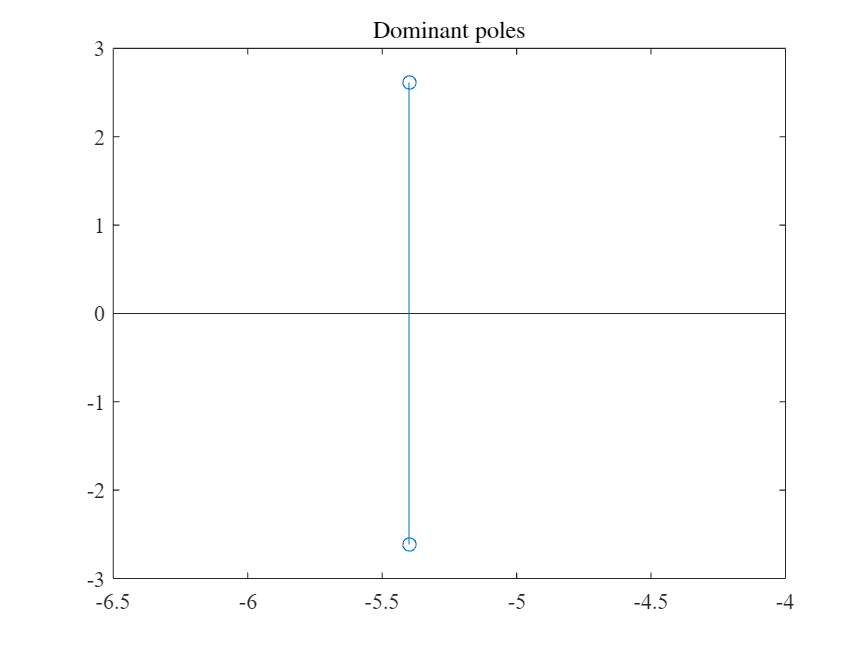

stem(real(poles(2:3)),imag(poles(2:3)))
title("Dominant poles")

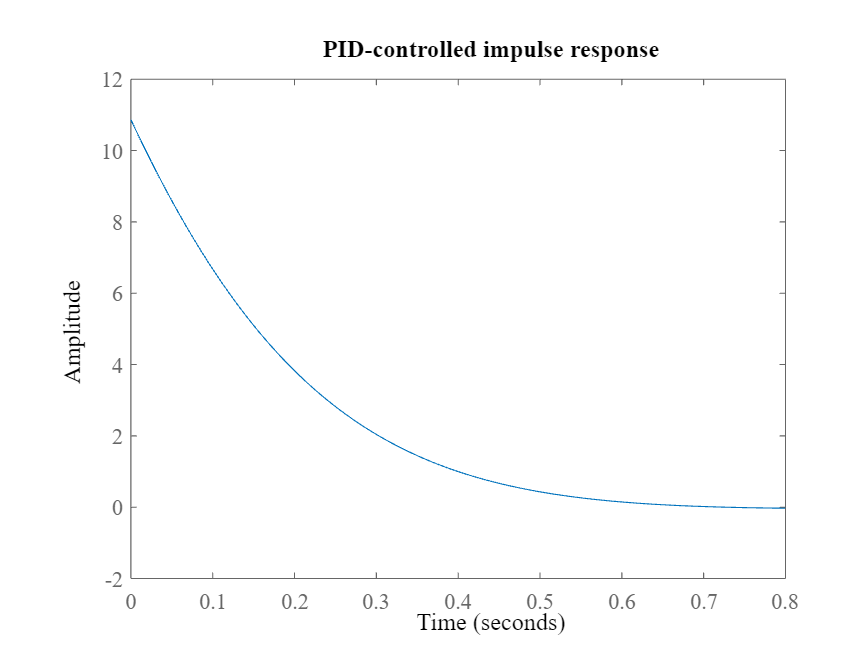


impulse(CLTF)
title("PID-controlled impulse response")

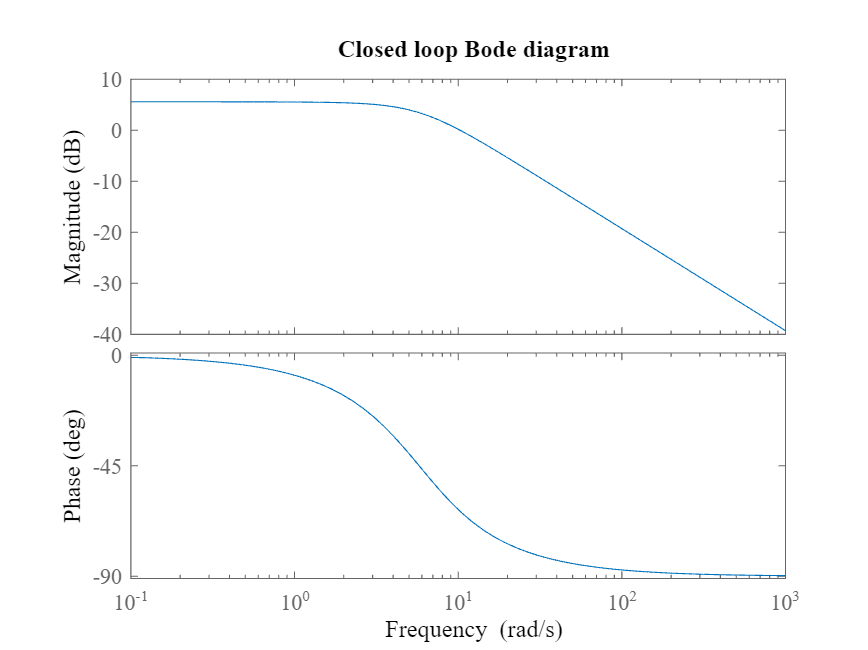

bode(CLTF)
title("Closed loop Bode diagram")

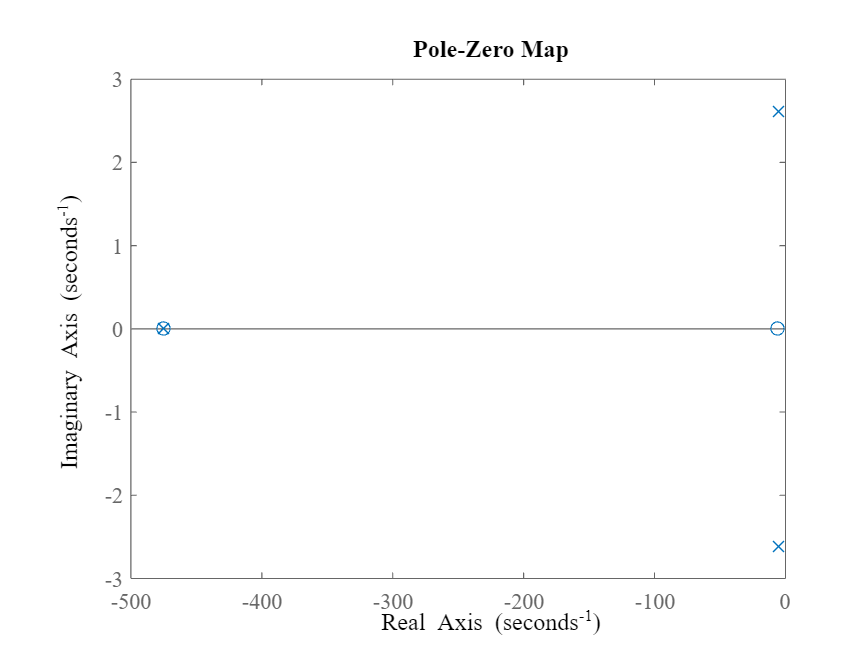

pzmap(CLTF)

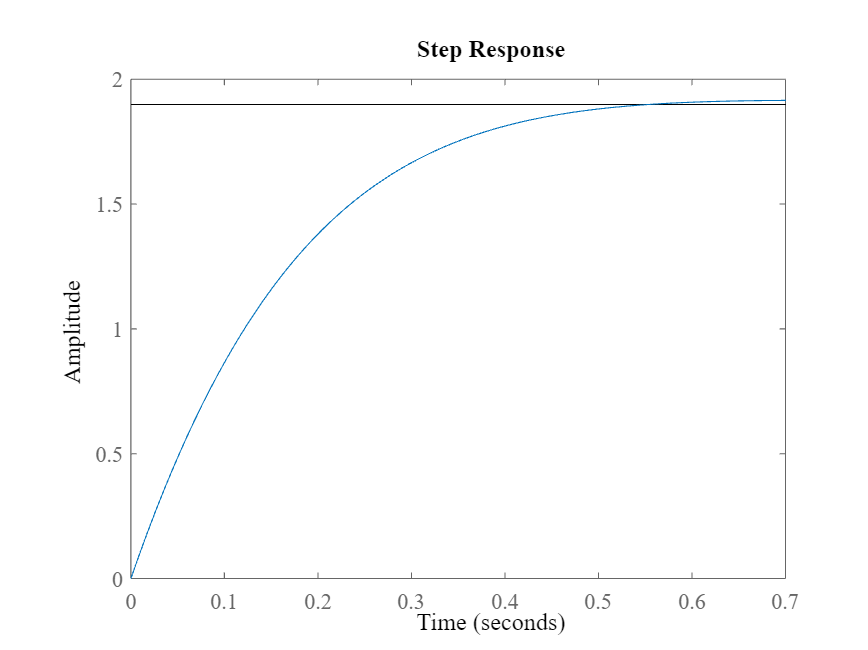

% %Note infinite gain margin but limited(though massive) phase margin

step(CLTF)


%Converting to discrete time
wb = bandwidth(CLTF) %Bandwith rad/s

wb =    6.9065e+00


fb = wb/(2*pi) %Bandwidth Hz

fb =    1.0992e+00


Fs =  25*fb %Sampling frequency

Fs =    2.7480e+01


Ts = 1/Fs  %Sampling Period

Ts =    3.6390e-02


simSamplePeriod = 0.00001

simSamplePeriod =    1.0000e-05


Tsd = floor(Ts/simSamplePeriod)*simSamplePeriod

Tsd =    3.6380e-02


round(Ts,1,"significant")

ans =    4.0000e-02




Kp = solNum(1)

Kp =   -5.8080e+01


Ki = solNum(2)

Ki =   -3.6071e+02


Kd = solNum(3)

Kd =   -1.2066e-01



save("LABA_CONT.mat","Kp","Ki","Kd","Ts","Tsd","simSamplePeriod","-append")


